 clear all
 close all
 path = 'InvestmentReplica.mat';
 load(path)

T = readtable("InvestmentReplica.CSV")

T = 705×16 table
       Date        MXWO      MXWD     LEGATRUU    HFRXGL     RX1       TY1       GC1      CO1      ES1       VG1       NQ1       LLL1      TP1       DU1       TU2  
    __________    ______    ______    ________    ______    ______    ______    _____    _____    ______    ______    ______    ______    ______    ______    ______

    23/10/2007    1633.4    414.14     350.21     1343.6     113.7    110.52      759    82.85    1525.5    

assetNames = ["RX1", "TY1", "GC1", "CO1", "ES1", "VG1", "NQ1","LLL1","TP1","DU1","TU2"];

% Synthetic target weights
wMXWO = 0.2; 
wMXWD = 0.2;
wLEGATRUU = 0.6;
%Primi due simili

% Building the target
y = wMXWD*price2ret(MXWD) + wMXWO*price2ret(MXWO) + wLEGATRUU*price2ret(LEGATRUU); % "Monster Index" returns
target = (ret2price(y)); % "Monster Index" levels

T.target = target;

benchmarkName = "target";
head(T(:,["Date" benchmarkName assetNames]))

       Date       target     RX1       TY1       GC1      CO1      ES1      VG1      NQ1       LLL1      TP1       DU1       TU2  
    __________    ______    ______    ______    _____    _____    ______    ____    ______    ______    ______    ______    ______

    23/10/2007         1     113.7    110.52      759    82.85    1525.5    4393      2212      1287    1570.5    103.39    103.72
    30/10/2007    1.0121    113.79    110.66    787.8    87.44      1536    4476    2217.8    1323.9    1610.5    103.41    103.81
    06/11/2007    1.0116    113.7

retnsT = tick2ret(T(:, 2:end));
assetRetns = retnsT(:, assetNames);
benchRetn = retnsT(:, benchmarkName);
numAssets = size(assetRetns, 2);

v = 3;  % total 3 views
P = zeros(v, numAssets);
q = zeros(v, 1);
Omega = zeros(v);

% View 1
P(1, assetNames=="RX1") = 1; 
q(1) = 0.05;
Omega(1, 1) = 1e-3;

% View 2
P(2, assetNames=="TY1") = 1; 
q(2) = 0.03;
Omega(2, 2) = 1e-3;

% View 3
P(3, assetNames=="GC1") = 1; 
P(3, assetNames=="CO1") = -1; 
q(3) = 0.05;
Omega(3, 3) = 1e-5;

viewTable = array2table([P q diag(Omega)], 'VariableNames', [assetNames "View_Return" "View_Uncertainty"]) 

viewTable = 3×13 table
    RX1    TY1    GC1    CO1    ES1    VG1    NQ1    LLL1    TP1    DU1    TU2    View_Return    View_Uncertainty
    ___    ___    ___    ___    ___    ___    ___    ____    ___    ___    ___    ___________    ________________

     1      0      0      0      0      0      0      0       0      0      0        0.05             0.001      
     0      1      0      0      0      0      0      0       0      0      0        0.03             0.001      
     0      0      1     -1      0      0      0      0       0      0      0 

bizyear2bizweek = 1/52; %da anno a settimana
q = q*bizyear2bizweek; 
Omega = Omega*bizyear2bizweek;

Sigma = cov(assetRetns.Variables);

tau = 1/size(assetRetns.Variables, 1);
C = tau*Sigma;

[wtsMarket, PI] = findMarketPortfolioAndImpliedReturn(assetRetns.Variables, benchRetn.Variables);

mu_bl = (P'*(Omega\P) + inv(C)) \ ( C\PI + P'*(Omega\q));
cov_mu = inv(P'*(Omega\P) + inv(C));

table(assetNames', PI*252, mu_bl*252, 'VariableNames', ["Asset_Name", ...
    "Prior_Belief_of_Expected_Return", "Black_Litterman_Blended_Expected_Return"])

ans = 11×3 table
    Asset_Name    Prior_Belief_of_Expected_Return    Black_Litterman_Blended_Expected_Return
    __________    _______________________________    _______________________________________

      "RX1"                  -0.018675                             0.00084298               
      "TY1"                   -0.00676                               0.020566               
      "GC1"                      0.147                                0.19363               
      "CO1"                    0.43395                              -0.027008               
      "ES1"                    0.35289                                  0.267               
      "VG1"                    0.40214                                0.29276               
      "NQ1"                    0.36175                                0.27384               
      "LLL1"                   0.25095     

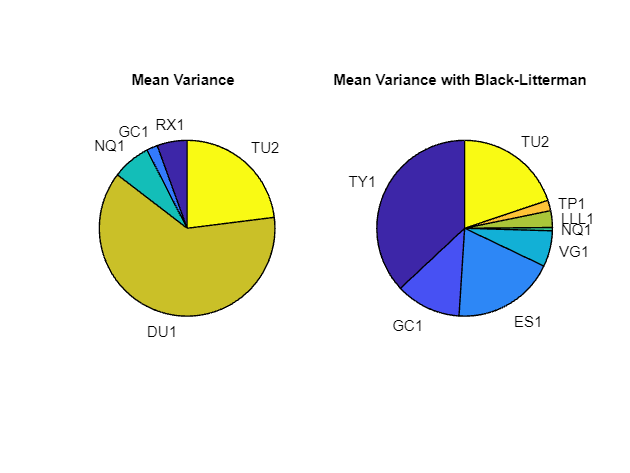

port = Portfolio('NumAssets', numAssets, 'lb', 0, 'budget', 1, 'Name', 'Mean Variance');
port = setAssetMoments(port, mean(assetRetns.Variables), Sigma);
wts = estimateMaxSharpeRatio(port);

portBL = Portfolio('NumAssets', numAssets, 'lb', 0, 'budget', 1, 'Name', 'Mean Variance with Black-Litterman');
portBL = setAssetMoments(portBL, mu_bl, Sigma + cov_mu);  
wtsBL = estimateMaxSharpeRatio(portBL);

ax1 = subplot(1,2,1);
idx = wts>0.001;
pie(ax1, wts(idx), assetNames(idx));
title(ax1, port.Name ,'Position', [-0.05, 1.6, 0]);

ax2 = subplot(1,2,2);
idx_BL = wtsBL>0.001;
pie(ax2, wtsBL(idx_BL), assetNames(idx_BL));
title(ax2, portBL.Name ,'Position', [-0.05, 1.6, 0]);

table(assetNames', wts, wtsBL, 'VariableNames', ["AssetName", "Mean_Variance", ...
     "Mean_Variance_with_Black_Litterman"])

ans = 11×3 table
    AssetName    Mean_Variance    Mean_Variance_with_Black_Litterman
    _________    _____________    __________________________________

     "RX1"          0.055299                  7.0707e-12            
     "TY1"        2.9327e-15                     0.36963            
     "GC1"          0.020185                     0.12017            
     "CO1"        7.3194e-15                  8.7853e-15            
     "ES1"        6.6158e-15                     0.18943            
     "VG1"        1.4796e-15                    0.066072            
     "NQ1"          0.070498                   0.0060662            
     "LLL1"       1.0558e-15                    0.030668            
     "TP1"        5.3565e-13                    0.019473            
     "DU1"           0.62379                  5.5332e-12            
     "TU2"           0.23023                     0.1